# Motor Torque Sizing based on the Joint Angle data of the Left Leg exoskeleton

clear
close all
clc


Initialization of the respective joint angles

syms tau_ankle tau_knee tau_hip real

g = 9.807

g = 9.8070

m_thigh = 11

m_thigh = 11

m_leg = 5.115

m_leg = 5.1150

m_foot = 1.595

m_foot = 1.5950


l_fl = .2736

l_fl = 0.2736

l_foot = 0.0709

l_foot = 0.0709

l_leg = 0.4428

l_leg = 0.4428

l_thigh = 0.441

l_thigh = 0.4410



time_period = 0:2:10

time_period =      0     2     4     6     8    10


theta_1 = [0 0.65 0.7 0.6 0.55 0.65]

theta_1 =          0    0.6500    0.7000    0.6000    0.5500    0.6500


theta_2 = [1.5 .55 .5 .25 .55 .55]

theta_2 =     1.5000    0.5500    0.5000    0.2500    0.5500    0.5500


theta_3 = [1.6 1.95 2 2.35 2.1 1.95]

theta_3 =     1.6000    1.9500    2.0000    2.3500    2.1000    1.9500


tau_ankle = m_foot*g*cos(theta_3)*(l_fl/2)

tau_ankle =    -0.0625   -0.7921   -0.8905   -1.5037   -1.0803   -0.7921


tau_knee = m_leg*g*sin(theta_2)*(l_leg/2) + m_foot*g*(l_leg*sin(theta_2) + cos(theta_3)*(l_fl/2))

tau_knee =    17.9247    8.6332    7.7547    2.9576    8.3450    8.6332


tau_hip = m_thigh*g*sin(theta_1)*(l_thigh/2) + m_leg*g*(l_thigh*sin(theta_1) + sin(theta_2)*(l_leg/2)) + m_foot*g*(l_thigh*sin(theta_1) + l_leg*sin(theta_2) + cos(theta_3)*(l_fl/2))

tau_hip =    17.9247   40.5912   41.7738   32.7746   35.9465   40.5912


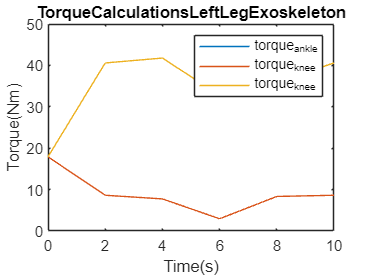

plot(time_period, tau_ankle)
hold on
plot(time_period, tau_knee)
plot(time_period, tau_hip)

legend(["torque_ankle","torque_knee","torque_knee"])

xlim([0.0 10.0])
ylim([0.0 50.0])
title("TorqueCalculationsLeftLegExoskeleton")
xlabel("Time(s)")
ylabel("Torque(Nm)")